x_0 = [0,100,0,0,pi/2,0];
TrajOptimizer(x_0,[],[],vehicle, true)

x_0 = [0,0,100,0,0,0,0,pi/2,0,0,0];
TrajOptimizer5DoF(x_0,[],[],vehicle, true);

This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:    21560
Number of nonzeros in inequality constraint Jacobian.:     3200
Number of nonzeros in Lagrangian Hessian.............:     8382

Total number of variables............................:     5600
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     4403
Total number of inequality constraints...............:     1600
        inequality constraints with only lower bounds:     1200
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      400

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  6.4000000e+01 6.25e+00 5.51e-01  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

Error using casadi.Opti/solve (line 562)
Error in Opti::solve [OptiNode] at .../casadi/core/optistack.cpp:165:
.../casadi/core/optistack_internal.cpp:1030: Assertion "return_success(accept_limit)" failed:
Solver failed. You may use opti.debug.value to investigate the latest values of variables. return_status is 'Maximum_Iterations_Exceeded'

Error in <a href="matlab:matlab.lang.internal.introspective.errorDocCallback('TrajOptimizer5DoF', 'C:\Users\thatf\OneDrive\Documents\ASA\AC Optimal Control\PSP-ASA-Optimal-Control-AC\Dynamics Models\5DoF\TrajOptimizer5DoF.m', 110)" style="font-weight:bold">TrajOptimizer5DoF<

hold off;

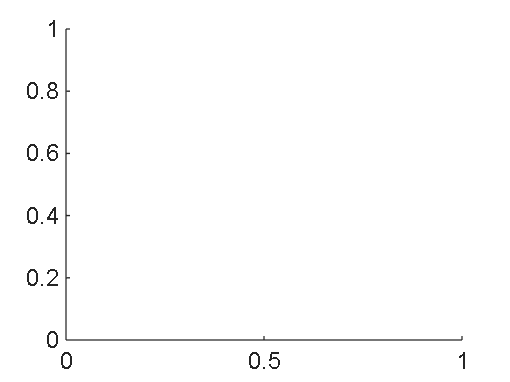

vehicle = load("Astra2").vehicle;
dof = DoF.euler5DoF;
tspan = [0 5];
x0 = [0,0,100,0,10,0,0,pi/2,0,0,0];
[t,y] = ode45(@(t,y) Dynamics_nDoF(y, [0,0,0], vehicle, dof), tspan, x0);
hold off;

% position
plot(t,y(:,1),t,y(:,2),t,y(:,3))
legend("x","y","z")

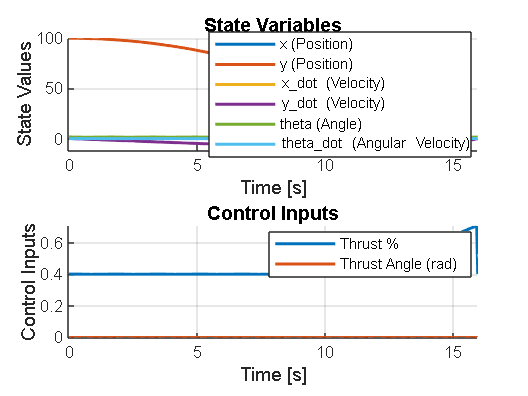

% velocity
plot(t,y(:,4),t,y(:,5),t,y(:,6))

legend("vx","vy","vz")

% orientation
plot(t,y(:,7),t,y(:,8),t,y(:,9))
legend("e1_1","e2_2","e1_3")

% angular velocity
plot(t,y(:,10),t,y(:,11))
legend("wx","wy")